В этом скрипте будет производиться проверка и калибровка конвеера PCA для внедрения в другой проект.

mu = [-10 15 4];
sigma = [1.2 1 1; 1 1.2 1; 1 1 1]

sigma =     1.2000    1.0000    1.0000
    1.0000    1.2000    1.0000
    1.0000    1.0000    1.0000


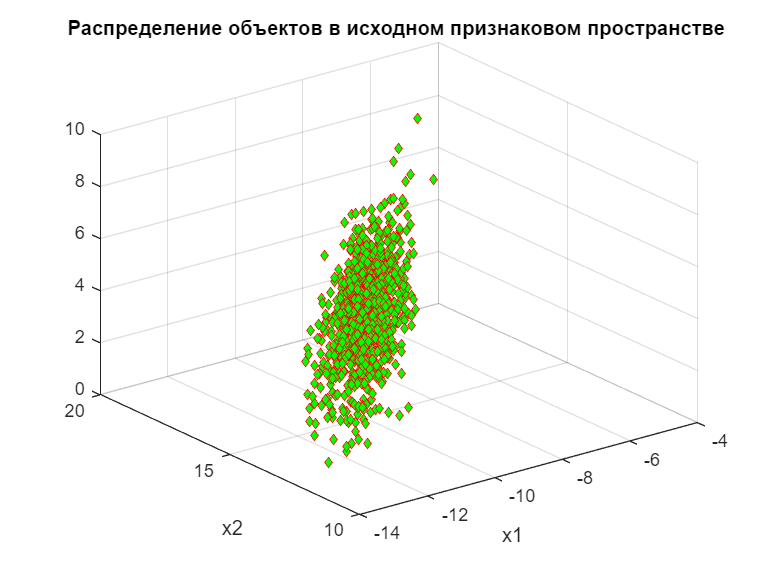

m = 1000;
x = mvnrnd(mu,sigma,m);
% figure;scatter(x(:,1),x(:,2), ...
%     'MarkerFaceColor','g', ...
%     'MarkerEdgeColor','r', ...
%     'AlphaData',0.5,...
%     'Marker','d', ...
%     'SizeData',15);
% xlabel('x1');
% ylabel('x2');
% title('Распределение объектов в исходном признаковом пространстве ');
figure;scatter3(x(:,1),x(:,2),x(:,3), ...
    'MarkerFaceColor','g', ...
    'MarkerEdgeColor','r', ...
    'AlphaData',0.5,...
    'Marker','d', ...
    'SizeData',15);
xlabel('x1');
ylabel('x2');
title('Распределение объектов в исходном признаковом пространстве ');

feature_mean_values = mean(x,1);%средние значения признаков x1,x2

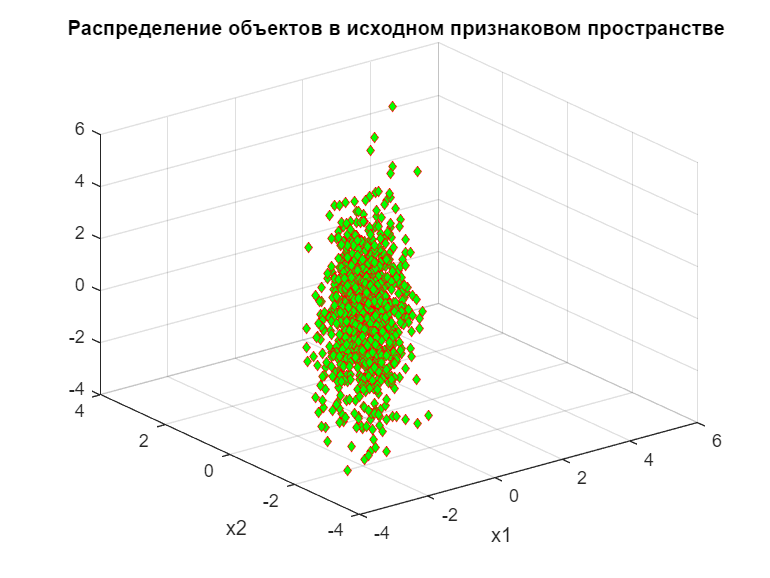

x_av = x - feature_mean_values;

% figure;scatter(x_av(:,1),x_av(:,2), ...
%     'MarkerFaceColor','g', ...
%     'MarkerEdgeColor','r', ...
%     'AlphaData',0.5,...
%     'Marker','d', ...
%     'SizeData',15);
% xlabel('x1');
% ylabel('x2');
% title('Распределение объектов в центрированном признаковом пространстве ');

figure;scatter3(x_av(:,1),x_av(:,2),x_av(:,3), ...
    'MarkerFaceColor','g', ...
    'MarkerEdgeColor','r', ...
    'AlphaData',0.5,...
    'Marker','d', ...
    'SizeData',15);
xlabel('x1');
ylabel('x2');
title('Распределение объектов в исходном признаковом пространстве ');

%вычисление ковариационной матрицы
cov_matrix1 = 1/m*x_av'*x_av

cov_matrix1 =     1.1816    0.9776    1.0035
    0.9776    1.1504    0.9796
    1.0035    0.9796    1.0125


cov_matrix2 = cov(x_av)

cov_matrix2 =     1.1828    0.9786    1.0045
    0.9786    1.1515    0.9805
    1.0045    0.9805    1.0135


%Сингулярное разложение матрицы Singular Value Decomposition
[U,S,V] = svd(cov_matrix1)

U =    -0.5915    0.6848   -0.4256
   -0.5806   -0.7280   -0.3645
   -0.5594    0.0315    0.8283


S =     3.0902         0         0
         0    0.1884         0
         0         0    0.0658


V =    -0.5915    0.6848   -0.4256
   -0.5806   -0.7280   -0.3645
   -0.5594    0.0315    0.8283


%Столбцы U - собственные вектора
%Числа на диагонали S - собственные числа

[V D] = eig(cov_matrix1)

V =    -0.5915   -0.6848   -0.4256
   -0.5806    0.7280   -0.3645
   -0.5594   -0.0315    0.8283


D =     3.0902         0         0
         0    0.1884         0
         0         0    0.0658


%Столбцы V - собственные вектора
%Числа на диагонали D - собственные числа

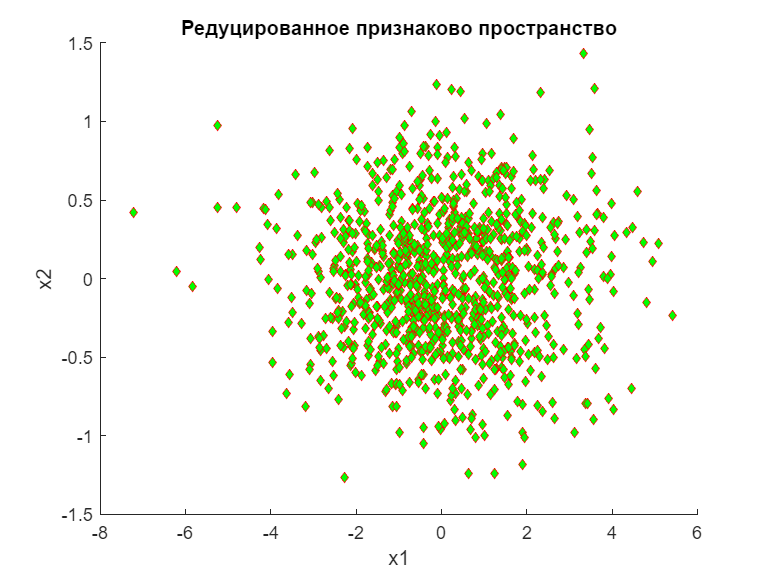

k = 2;%Число компонент на выходе
Ureduce = U(:,1:k);
z = x_av*Ureduce; %проекция всех объектов на первых k собственных векторов через скалярное произведение

figure;scatter(z(:,1),z(:,2), ...
    'MarkerFaceColor','g', ...
    'MarkerEdgeColor','r', ...
    'AlphaData',0.5,...
    'Marker','d', ...
    'SizeData',15);
xlabel('x1');
ylabel('x2');
title('Редуцированное признаково пространство');

%Восстановление исходного вектора x, но с потерями в дисперсии

x_approx = z*Ureduce';

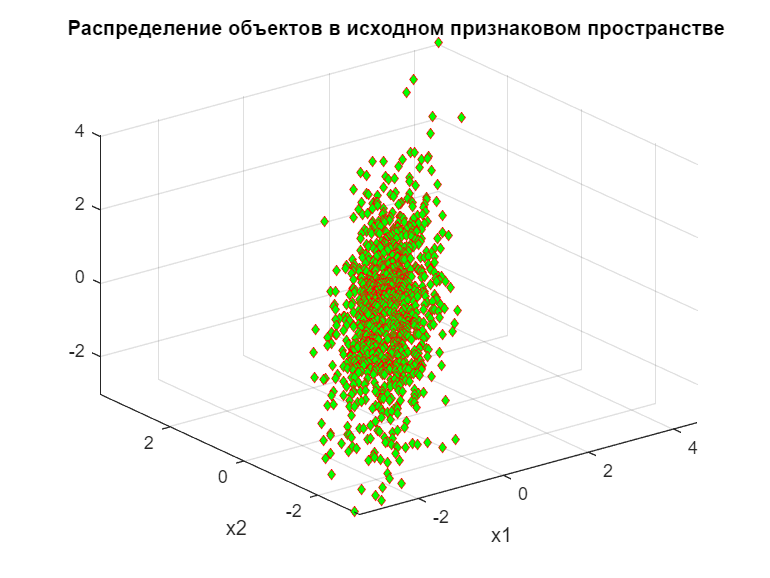

% figure;scatter(x_approx(:,1),x_approx(:,2), ...
%     'MarkerFaceColor','g', ...
%     'MarkerEdgeColor','r', ...
%     'AlphaData',0.5,...
%     'Marker','d', ...
%     'SizeData',15);
% xlabel('x1');
% ylabel('x2');
% title('Распределение объектов после восстановления');

figure;scatter3(x_approx(:,1),x_approx(:,2),x_approx(:,3), ...
    'MarkerFaceColor','g', ...
    'MarkerEdgeColor','r', ...
    'AlphaData',0.5,...
    'Marker','d', ...
    'SizeData',15);
xlabel('x1');
ylabel('x2');
title('Распределение объектов в исходном признаковом пространстве ');

cov_matrix3 = cov(x_approx)

cov_matrix3 =     1.1708    0.9684    1.0277
    0.9684    1.1427    1.0004
    1.0277    1.0004    0.9683


cov_matrix4 = cov(z)

cov_matrix4 =     3.0933   -0.0000
   -0.0000    0.1886


figure;scatter(z(:,1),z(:,2), ...
    'MarkerFaceColor','g', ...
    'MarkerEdgeColor','r', ...
    'AlphaData',0.5,...
    'Marker','d', ...
    'SizeData',15);
xlabel('x1');
ylabel('x2');
title('Распределение объектов после восстановления');

sigma

sigma =     1.5000   -1.0000   -2.0000
   -1.0000    5.0000   -4.0000
   -2.0000   -4.0000   10.0000
